tau=100;
s=40;%nm/s

diam =900;
dt=1;
nFr=120;

%angular velocity omega=v/r
omega=2*s/diam;
dTheta=omega*dt;

%need to generate
% t_n (integer),theta_n, x_n, y_n
%generate midpoint of track, [t,theta]
tauFr=tau/dt;%track length in frames
frMid=randi(nFr);
thetaMid=rand*2*pi;
%calculate start and end points
frStart=max(1,round(frMid-tauFr/2));
frEnd=min(nFr,round(frMid+tauFr/2));
trackLenFr=frEnd-frStart+1;

thetaStart=mod(thetaMid-(frMid-frStart)*dt*omega,2*pi);

fr=[frStart:1:frEnd]';
t=fr/dt;
thetaRaw=[thetaStart:dTheta:thetaStart+dTheta*(trackLenFr-1)]';
theta=mod(thetaRaw,2*pi);
x=cos(theta)*diam/2;
y=sin(theta)*diam/2;

a few sanity checks on the above prototype code

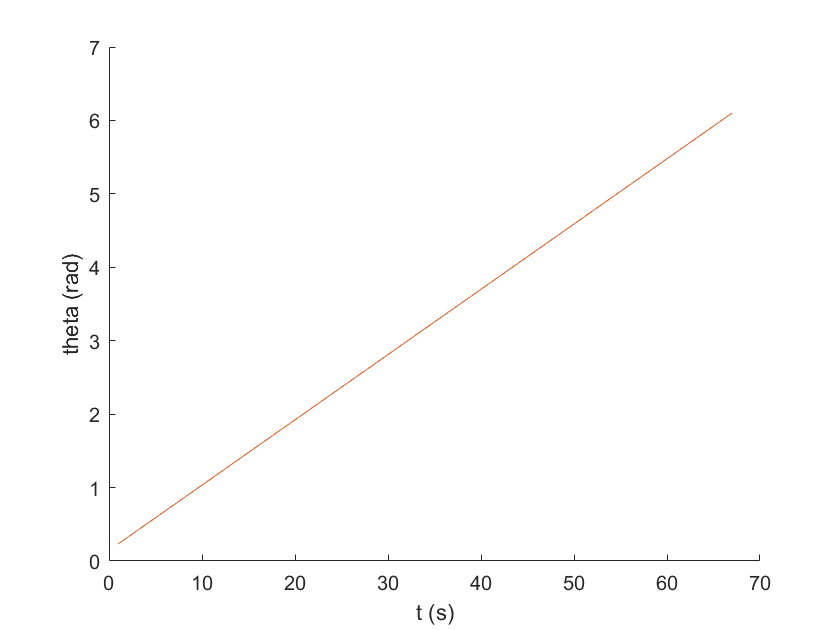

figure;
hold all;
plot(t,theta);
plot(t,thetaRaw);
xlabel('t (s)')
ylabel('theta (rad)');

omegaCheck=(thetaRaw(2)-thetaRaw(1))/(t(2)-t(1))

omegaCheck = 0.0889

sCheck=omegaCheck*diam/2

sCheck = 40.0000

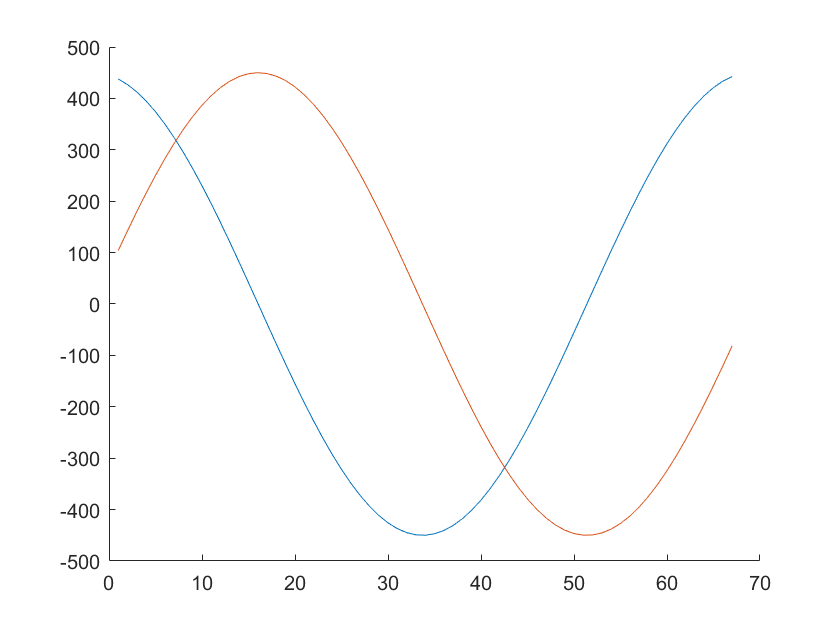

figure;
hold all;
plot(t,x);
plot(t,y);

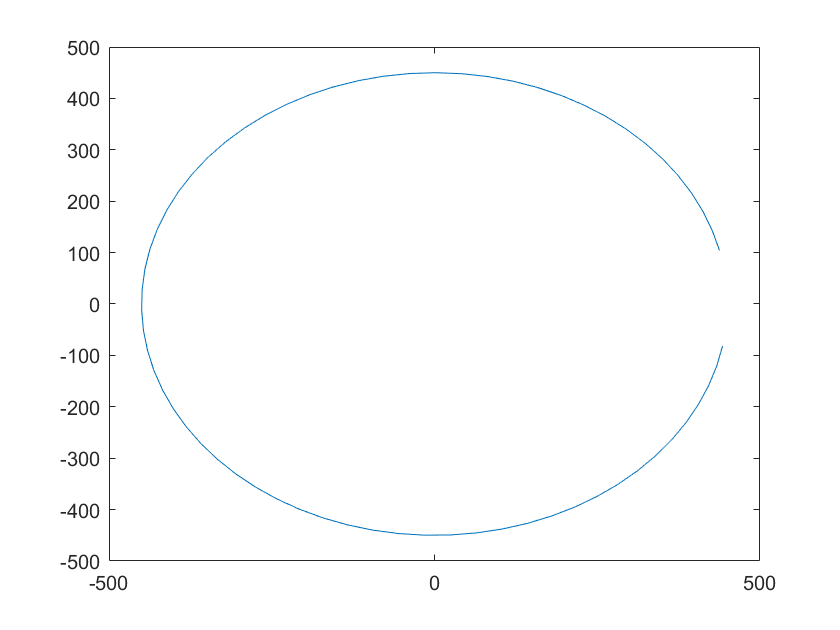

figure
plot(x,y);

trackCoord=table;
trackCoord.fr=fr;
trackCoord.t=t;
trackCoord.theta=theta;
trackCoord.x=x;
trackCoord.y=y;

check simulator implementaion gives consistent results

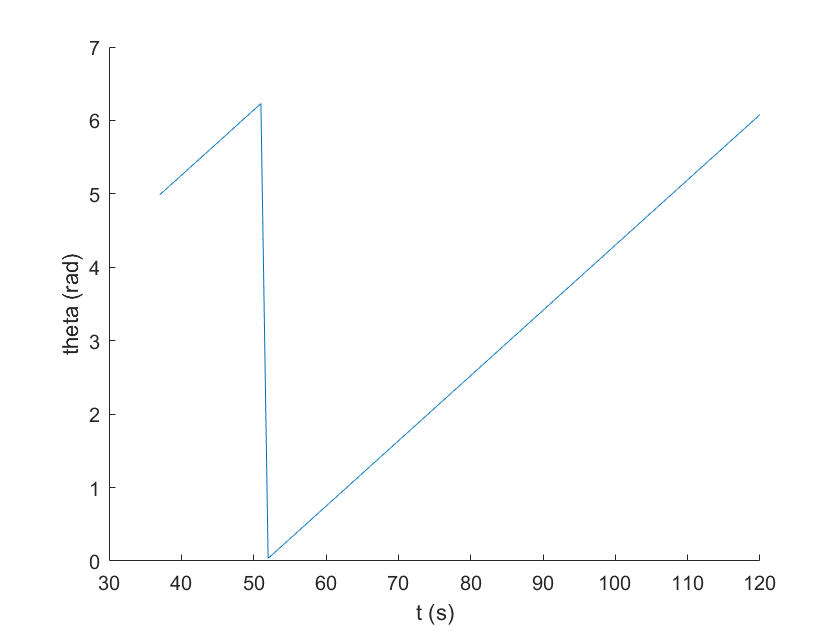

trackCoord2=genTrackCoord(tau,s,diam,dt,nFr);

figure;
hold all;
plot(trackCoord2.t,trackCoord2.theta);
xlabel('t (s)')
ylabel('theta (rad)');

omegaCheck=(trackCoord2.theta(2)-trackCoord2.theta(1))/(t(2)-t(1))

omegaCheck = 0.0889

sCheck=omegaCheck*diam/2

sCheck = 40.0000

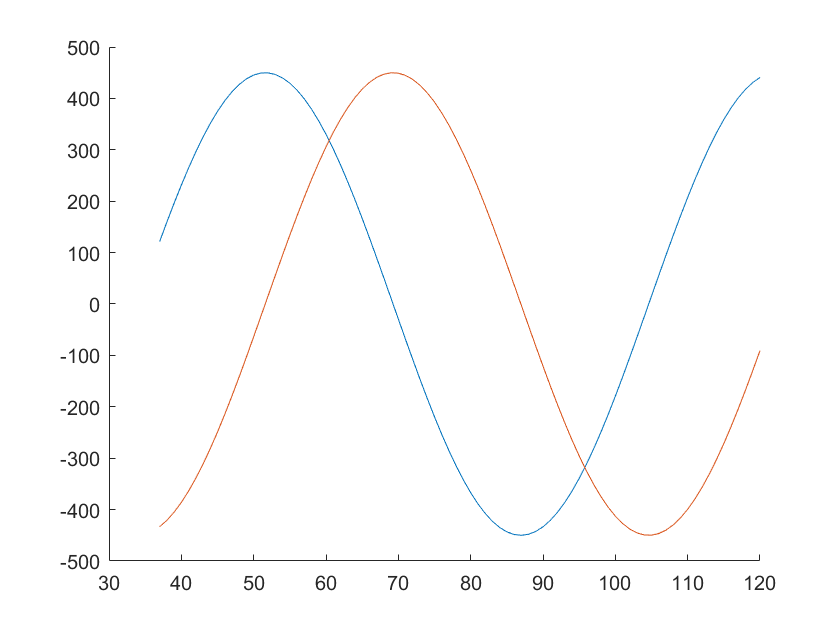

figure;
hold all;
plot(trackCoord2.t,trackCoord2.x);
plot(trackCoord2.t,trackCoord2.y);

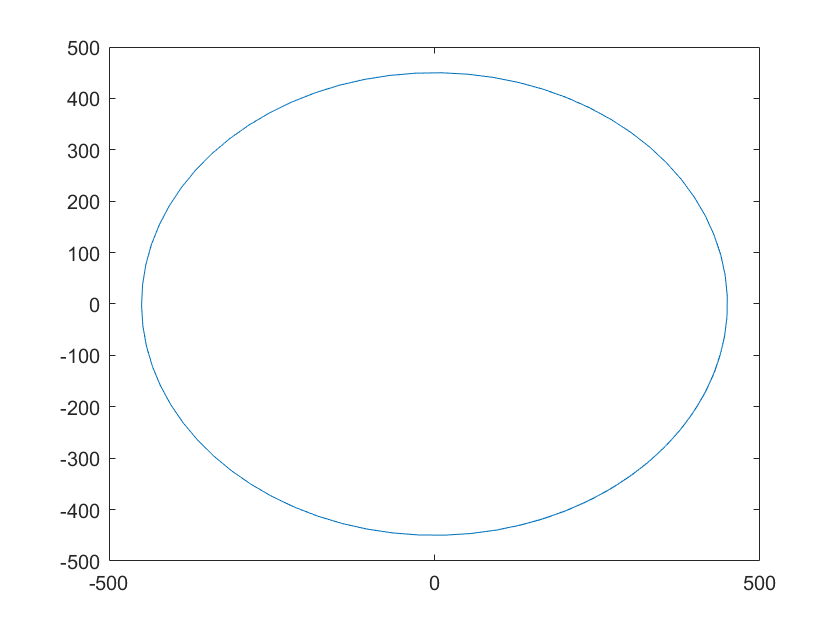

figure
plot(trackCoord2.x,trackCoord2.y);

% %save a test dataset
% track=trackCoord;
% save('testTrackSpatial.mat','track');